2021年11月20日

# シミュレーション　講義ノートNo.0

#### 藤原　哉

#### 農林中央金庫

## 1.  はじめに

### 自己紹介

氏名：藤原　哉（ふじわら　はじめ）

所属：農林中央金庫 リスク評価部 内部モデル管理室

連絡先：fujiwara.hjm1972@gmail.com

略歴：

　証券会社(日興證券、東京三菱証券、野村證券）で主にデリバティブの価格評価モデルの開発を担当、金融庁で大手証券会社の規制内部モデルの承認審査・モニタリングを担当する。

現職場ではリスク計測／時価評価モデルの開発を担当している。モンテカルロ・シミュレーションはデリバティブの時価評価モデルの実装のときに使用していた経験がある。

### 講義の目的

モンテカルロ・シミュレーションの原理・手法を理解し、研究・実務での利用の「きっかけ」を作ること。

プログラミングの基礎的なお作法を学ぶこと。

### 講義の環境

Matlab onlineを利用すること。講義用資料はMatlabのライブスクリプトで作成し配布する。

課題のレポートもMatlabのライブスクリプトで作成すること。

### **Disclaimer**

本講義での資料の内容・発言は講師の個人的な意見であり、所属する組織の見解を表したものではない。

## 2. 講義のアウトライン

### 第０回講義（2021/11/20)

- 講義・演習の環境について(Matlab online)

- Matlab ライブスクリプトの利用方法

- Matlabでのプログラム作成方法

### 第１回講義(2021/11/27)

- モンテカルロ・シミュレーションを支える数学

- シミュレーションの誤差

**参考文献**

杉田洋,「確率と乱数」, 数学書房選書 4, 数学書房, 2014.

伏見正則, 「乱数」, UP数学応用選書 12, 東京大学出版会, 1989.

船木直久, 「確率論」, 講座数学の考え方 20, 朝倉書店, 2004.

### 第２回講義(2021/12/4)

- モンテカルロ・シミュレーションによる定積分の評価

- モンテカルロ・シミュレーションによる微分の評価

- 分散低減法 

**参考文献**

湯前祥二, 鈴木輝好, 「モンテカルロ法の金融工学への応用」, シリーズ＜現代金融工学＞ 6, 朝倉書店, 2000.

P. Glasserman, *Monte Carlo Methods in Financial Engineering, *Springer, 2003.

### 第３回講義(2021/12/11)

- 分散低減法（続き）

- 準モンテカルロ法

**参考文献**

湯前祥二, 鈴木輝好, 「モンテカルロ法の金融工学への応用」, シリーズ＜現代金融工学＞ 6, 朝倉書店, 2000.

P. Glasserman, *Monte Carlo Methods in Financial Engineering, *Springer, 2003.

C. Lemieux, *Monte Carlo and Quasi-Monte Carlo Sampling, *Springer, 2009.

G. Leobacher and F. Pillichshammer, *Introduction to Quasi-Monte Carlo Integration and Applications, *Birkhauser, 2013.

### 第４回講義(2021/12/18)

- 確率過程のシミュレーション

- 確率微分方程式の離散近似

**参考文献**

藤田岳彦, 「ランダムウォークと確率解析　ギャンブルから数理ファイナンス」, 日本評論社, 2008. 

P. Glasserman, *Monte Carlo Methods in Financial Engineering, *Springer, 2003.

G. Pages, *Numerical Probability An Introduction with Application to Finance*, Springer, 2018.

### 第５回講義(2021/12/25)

- 分散低減法

- マルチレベル法

**参考文献**

木島正明, 田中敬一, 「資産の価格付けと測度変換」,  朝倉書店, 2007.

M. B. Giles, *Multilevel Monte Carlo Methods*, Acta Numerica, 2018.

### 第６回講義(2022/1/8)

- モンテカルロ・シミュレーションによる条件付期待値の評価

- アメリカン・モンテカルロ法

**参考文献**

D. Belomestny and J. Shoenmakers, *Advanced Simulation-Based Methods for Optimal Stopping and Control, *Palgrave Macmillan, 2018.

P. Glasserman, *Monte Carlo Methods in Financial Engineering, *Springer, 2003.

### 第7回講義(2022/1/15)

- デフォルト（倒産）を考慮したシミュレーション

- シミュレーションによるCVAの評価

**参考文献**

J. Gregory, *The xVA Challenge: Counterpary Risk, Funding, Collateral, Capital and Initial Margin 4th ed. , *Wiley 2020. 

## 3. Matlab onlineを使おう

　Matlabが利用できるアカウントを持っていればブラウザ（Google Chromeなど）からMatlabが使える（Matlab online)。

Matlab onlineの利点は次の通りである。

- 自分のPCにMatlabをインストールする必要がない

- 計算環境はクラウドで用意されるので、個人のPCのスペックは関係がない

- 都立大学のアカウントであれば、すべてのToolboxがログインした時点で利用可能となっている

特に講義では、参加者の実行環境を揃えることが出来る利点がある。

そのため、個人のPCにMatlabをインストールしていても、Matlab onlineを利用するようにしてほしい。

#### Matlab onlineへのログインと受講の準備

「Matlab online」で検索してMathworks社の該当ページからログインする。

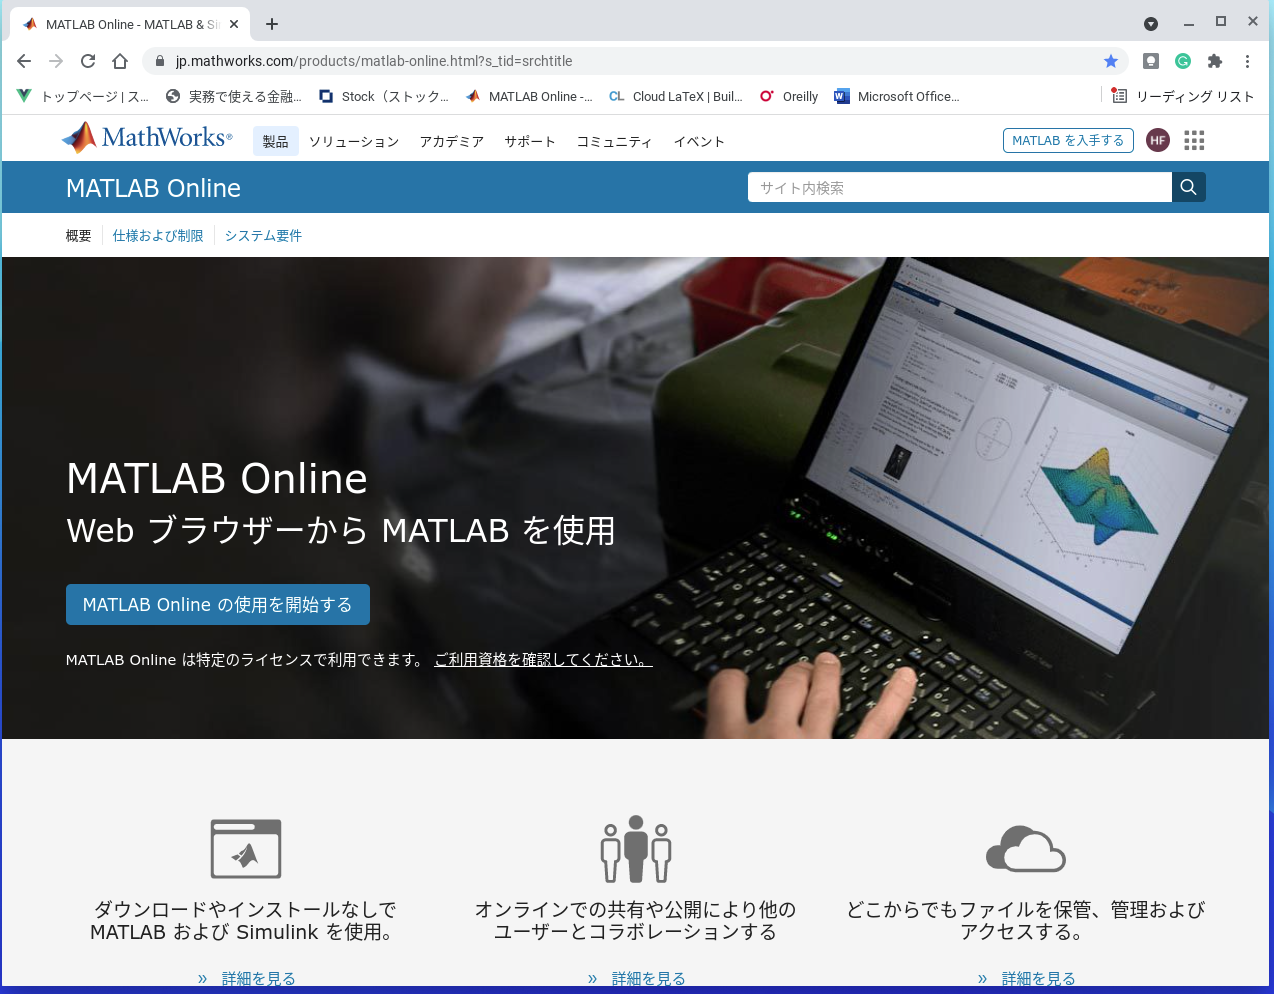

ログインするためにはアカウント（ID・パスワード）が必要である。別途、教務から配布されている資料を参考にしてアカウント作成すること。

ログインすると以下のような状態になるはず（赤い囲み、青い囲みは以下での説明で使うために追記している）。

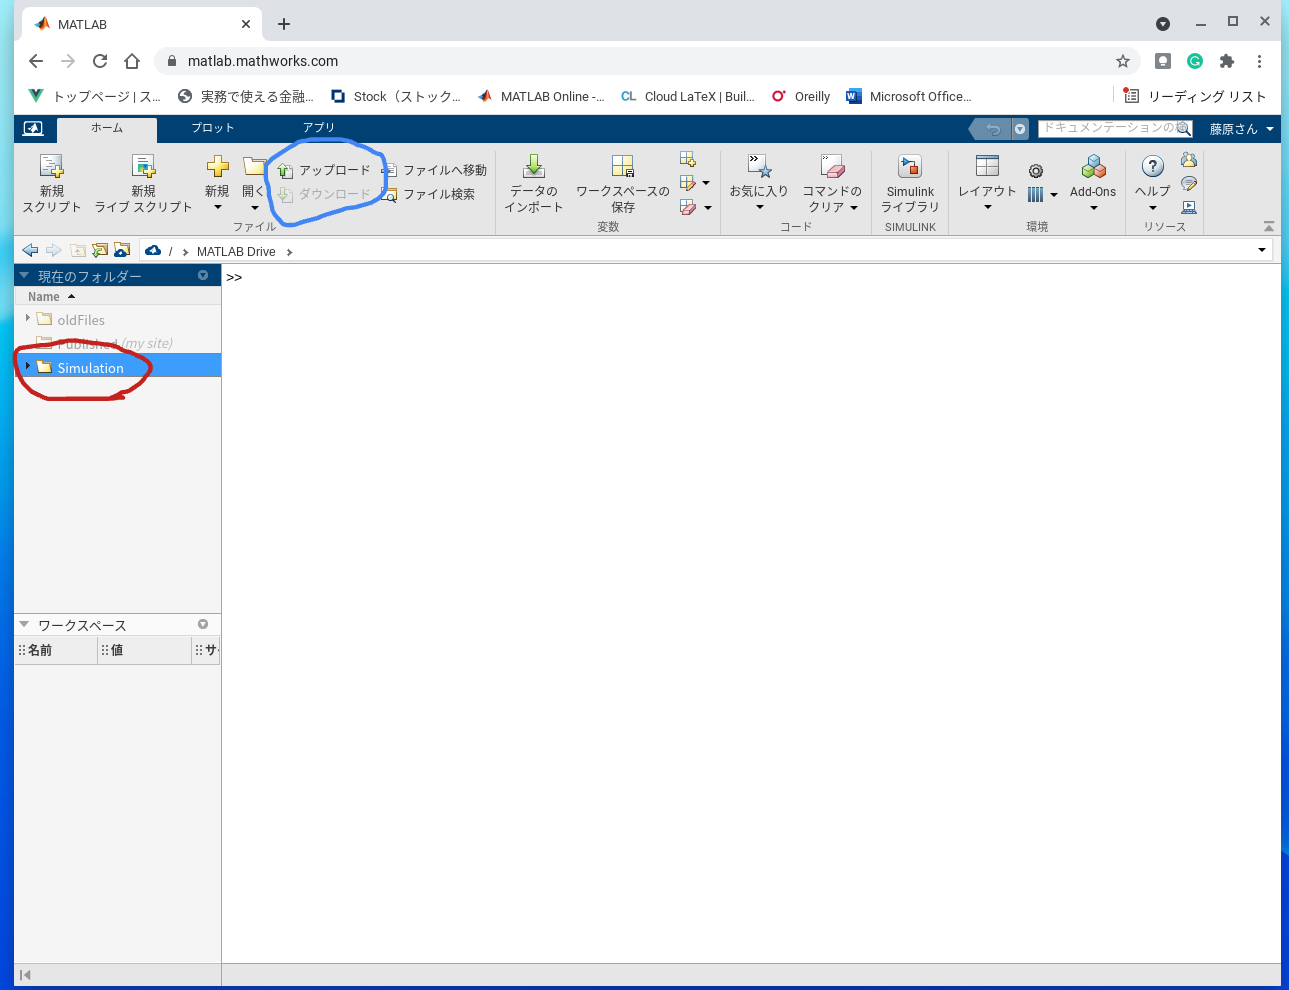

Matlab onlineで利用するファイルはクラウド上で保存される。

個人のPCからのファイルのアップロード / ダウンロードは上の図の青で囲んでいる「アップロード」ボタン、「ダウンロード」ボタンを押下して行う。

講義資料の保存場所として、上の図の赤で囲んでいるように「現在のフォルダー」のところに「Simulation」フォルダーを作成する。

新しいフォルダーは「現在のフォルダー」のグレー範囲で「右クリック→新規→フォルダー」で作成できる。

今後、講師が提供する資料は、この「Simulation」フォルダーに保存すること。

### 4. MATLABを使ってみよう

Matlabには以下の4つの使い方がある。

#### 4-1. コマンドウィンドウに打ち込む(関数電卓のように使う）

Matlabには便利な関数が多数用意されているので、コマンドウィンドウだけでもそこそこ複雑な計算を簡単に実行できる。

また、コマンドウィンドウで簡単な関数を自分で定義することも可能である。

  例：$f(x) = x^2$を定義して積分値$\int_0^1 f(x) {\rm d}x$を求める。

この例では f = @(x) x.^2が自分で関数を定義している部分である。@(x) x.^2の部分は無名関数と呼ばれ、この部分だけで関数として作用する。

 f = @(x) x.^2とすることで、無名関数にfという名前を与えている。次のように無名関数を直接利用することも可能である。

integralはMatlabで用意されている数値積分を行う組込関数である。

#### 4-2. ファイルにスクリプトを保存して実行する（手順を記述する）

コマンドウィンドウに直接打ち込むと再利用ができない。

繰り返し使いたい場合には実行したいことをファイルに記述して保存して、そのファイルをコマンドウィンドウで実行する方法がある。

そのファイルのことをスクリプトファイルとよび、拡張子は.mとする決まりである。

スクリプトファイルを作成するためにはエディターを起動する必要がある。

下の図のように「ホーム」タグの「新規スクリプト」（赤い囲みで強調）を押す。

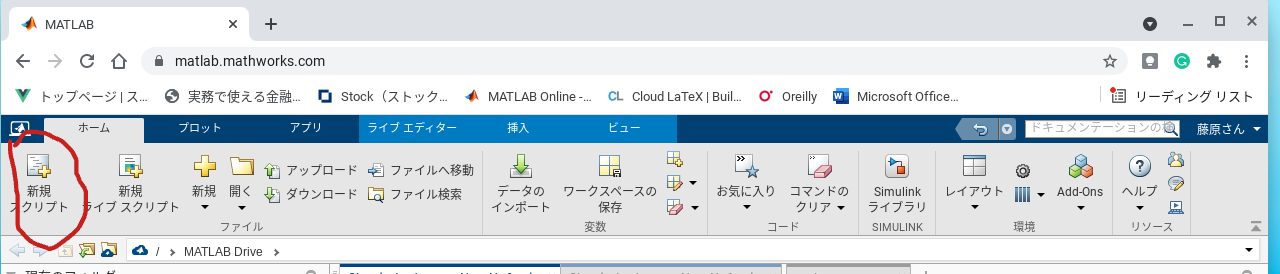

エディタが立ち上がり「untitled」のタグが出来る。

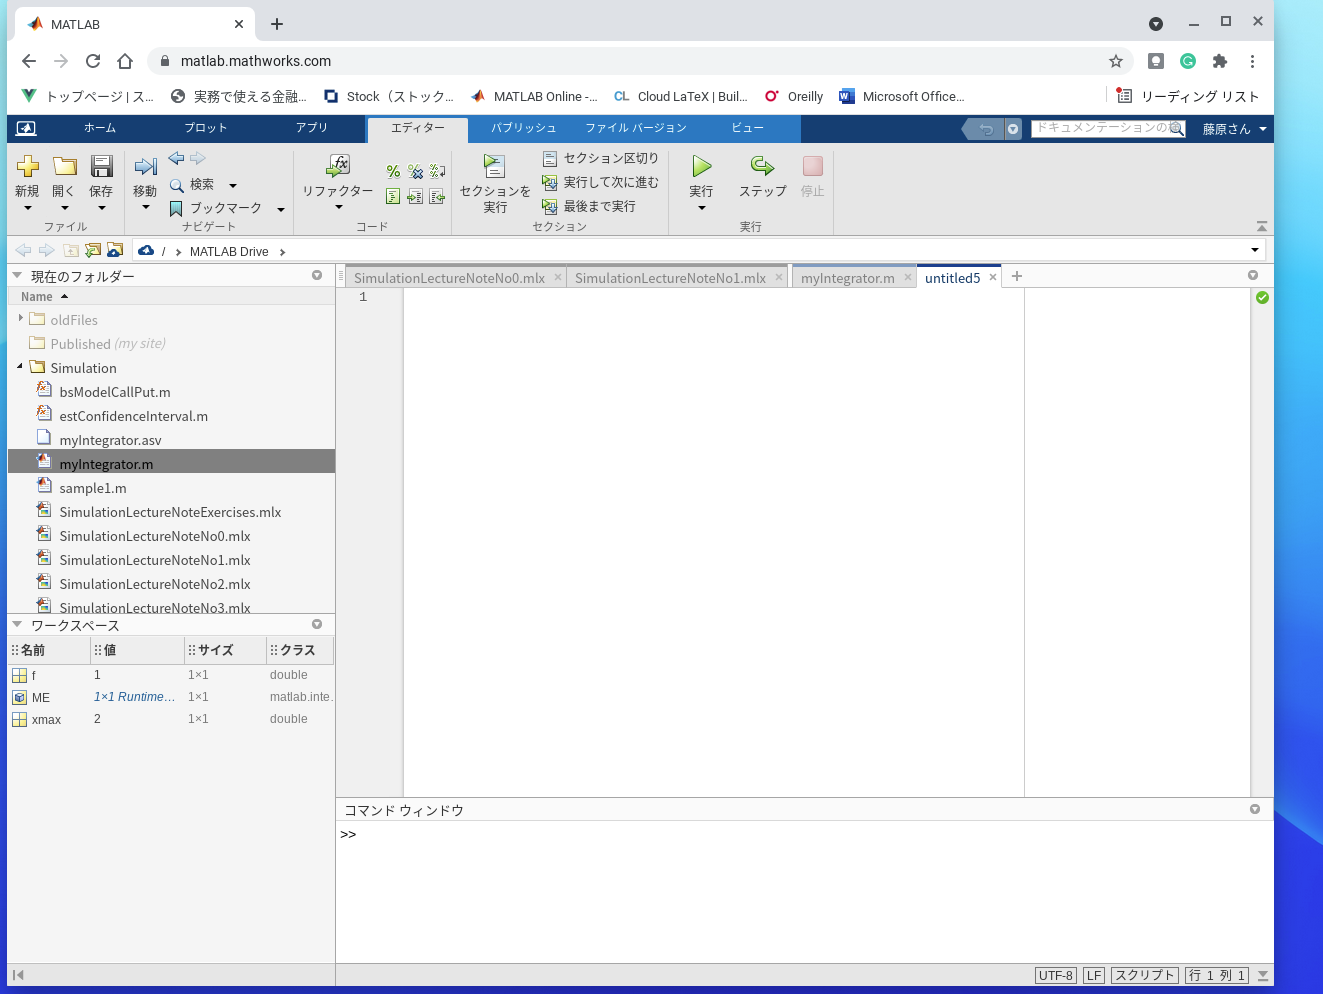

例えば$f(x) = x^2$を定義して積分値$\int_0^1 f(x) {\rm d}x$を求めることは、以下の内容をスクリプトファイルに記述しファイル名「sample1.m」として保存する。

コマンドウィンドウで「sample1」と入力して実行する。

#### 4-3. ファイルに関数を定義し、別のスクリプトファイルで実行する（プログラミング）

よく使う機能を関数として定義して他のスクリプトファイルや他の関数から再利用する。

例：任意の１変数関数$f : \mathbb{R} \longrightarrow \mathbb{R}$の０からx(>0)までの積分値を求める(汎)関数$F(f,x) = \int_0^x f(u) {\rm d} u$を関数ファイルに定義する。

関数名をmyIntegratorとし、myIntegrator.mファイルに関数の定義を記述する。関数名とファイル名は同じにしなければならない。

関数の定義で arguments ~ end の部分は入力チェックを行う部分であり、以下のように省略しても動作する。ただし、よく使う関数は誤動作を避けるためにarguments ~ end の部分を書いておいたほうがよい。

arguments~endがあると、関数の中身の実行前に入力変数の間違いをブロックする。

例えば、xmaxに負の数を入力すると

f = @(x) x.^2; % 2次関数の定義
xmax = -1; %% 間違って負の数を定義
try
    v1 = myIntegrator(f,xmax);
catch ME
    disp(ME.message);
end

位置 2 の引数が無効です。 値は非負でなければなりません。


fが関数がでない場合には

f = 1; % 関数ではなく定数を定義、定数の積分を実行したい
xmax = 2;
try 
    v1 = myIntegrator(f,xmax);
catch ME
    disp(ME.message);
end

位置 1 の引数が無効です。 値は function_handle 型であるか、function_handle に変換可能でなければなりません。


となる。正しくは

と定義すべきである。

try ~ catch ~ endはエラー処理（例外処理）のMatlabでの方法である。MEはエラー内容の詳細情報が含まれている。上の例ではエラーメッセージだけ表示している。

エラー情報MEに含まれている情報は次の通りである。

disp(ME);

  RuntimePositionalException のプロパティ:

        FunctionName: "myIntegrator"
        ArgumentName: "f"
    ArgumentPosition: 1
        CallSiteInfo: [1×1 struct]
          identifier: 'MATLAB:validation:UnableToConvert'
             message: '位置 1 の引数が無効です。 値は function_handle 型であるか、function_handle に変換可能でなければなりません。'
               cause: {}
               stack: [2×1 struct]
          Correction: []



なお、try ~ catch ~ endはある程度規模の大きなプログラムになると必要であるが、個人の研究レベルのプログラミングでは

使う必要性はあまりない。ここで使っているのはtry ~ catch ~ endでエラーを捕捉しないと以下のスクリプトが実行できないためである。

**ローカル関数**

プログラムの可読性を高めるために、ある特定ファイル内に限定された関数を定義して機能をまとめることもある。

このような関数をローカル関数という。スクリプトファイルでローカル関数を定義をする場合には、スクリプト記述の後ろにまとめて行う。

次のような記述を一つのスクリプトファイル内ではできないことに注意する(sample2.m)。

sample2.mを実行すると

とエラーになってしまう。

sample2を次のように書き換えると実行可能となる(sample3.m)。

sample3.mを実行すると

sample3;

     3

     2



と動作してることがわかる。

関数を定義して、その下に実行するスクリプトを書くsample2.mの方が自然な気もするが、Matlabでは「ローカル関数はファイルの最後に定義する」仕様となっている。

### 4-4. ドキュメントとスクリプトの一体化（ライブスクリプト）

この講義資料のように wordのようなドキュメント内にスクリプト、ローカル関数を記述できる形式をライブスクリプトという（ファイルの拡張子はmlx)。

同じような仕組みで有名なものにjupyter notebook (jupyter lab)がある。

jupyter notebookではローカルな関数やクラスを任意の位置で定義できるが、Matlabのライブスクリプトではスクリプトファイルと同様にローカル関数はファイルの最後にしか定義できない。また、クラスの定義はできない。

### 5. Matlabでの数値計算

Matlabでのデータはベクトル・行列で保持され、ベクトルや行列に対する各種演算が組み込まれているので、それらを活用することになる。

記号 $*,/$は行列としての掛算、割算であり、 $.*,./$は要素ごとの掛算、割算であることに注意する。

例えば $A=\pmatrix{1&2\cr3&4}, \ B = \pmatrix{5 & 6 \cr 7 & 8}$とすると

A = [1,2;3,4];
B = [5,6;7,8];

$A*B$は行列として掛算であり次のようになる。

disp(A*B);

  1 列

    19
    43

  2 列

    22
    50



$A.*B$は要素ごとの掛算であり次のようになる。

disp(A.*B);

  1 列

     5
    21

  2 列

    12
    32



$A/B$は $A*B^{-1}$を意味しており次のようになる。 $inv(B)$は 逆行列$B^{-1}$を表している。

disp(A/B);

  1 列

    3.0000
    2.0000

  2 列

   -2.0000
   -1.0000



disp(A*inv(B));

  1 列

    3.0000
    2.0000

  2 列

   -2.0000
   -1.0000



$A./B$は要素ごとの割算であり次のようになる。

disp(A./B);

  1 列

    0.2000
    0.4286

  2 列

    0.3333
    0.5000



行列計算を利用して次の連立方程式をMatlabで解いてみる。


$$\matrix{x + 2y & = & 5 \cr 3x+4y & = & 6}$$


$A = \pmatrix{1 & 2 \cr 3 & 4},\ b = \pmatrix{5 \cr 6}$とすると連立方程式は


$$A \pmatrix{x \cr y} = b$$
 

と表されるので、解は


$$\pmatrix{x \cr y} = A^{-1} b = \pmatrix{-4 \cr 4.5}$$


となる。これをMatlabでは以下のように解くことができる。

A = [1,2;3,4]; % 2x2行列の作成
b = [5;6]; % 2x1 ベクトルの作成

sol1 = inv(A)*b; % inv(A)はAの逆行列を返す。*は行列での掛け算を表す。
disp(sol1); %答えの表示

   -4.0000
    4.5000



sol2 = A\b; % inv(A)*bの別の表現、通常はこちらを用いる。
disp(sol2); %sol1と同じ値となる。

   -4.0000
    4.5000



**ミニ課題：鶴亀算**

鶴と亀が合わせて10000います。足の数は合わせて23456本です。鶴と亀はそれぞれ何羽・何匹いますか。

解：鶴の数を $x$、亀の数を $y$とすると


$$x+y = 10000 \\ 2x+4y = 23456$$


であるので行列表示では


$$\pmatrix{1&1 \cr 2 & 4} \pmatrix{x \cr y} = \pmatrix{10000 \cr 23456}$$


となる。よって、解は次のようになる。

A = [1,1;2,4];
b = [10000;23456];
sol = A\b;% inv(A)*b
disp(sol);

        8272
        1728



### 6. 関数を作ってみよう

簡単な例として 自然数 $n$の階乗 $n! = n\times(n-1)\times\cdots\times1$を求める関数を作る。

このファイルの最後にあるローカル関数のセクションで関数を定義する。

実装方法は次の２つとする。

ループによる実装 (myFactorial1)

$n=10$のときのmyFactorial1の実行結果

disp(myFactorial1(10));

     3628800



再帰による実装(myFactorial2)

$n=10$のときのmyFactorial2の実行結果

disp(myFactorial2(10));

     3628800



次に、三角形の各辺の長さを入力して直角三角形がどうか判定する関数を作ってみる。

直角三角形であれば true, 直角三角形であれば falseを返す。また、三角形ではない、例えば辺の長さの組が(5,1,1)の場合にはエラーを返す。

直角三角形の場合（5,4,3)での実行結果

disp(isRightTriangle(5,4,3));

   1



直角三角形でない場合(5,4,4)での実行結果

disp(isRightTriangle(5,4,4));

   0



三角形でない場合(5,4,1)での実行結果

try
    disp(isRightTriangle(5,4,1));
catch ME
    disp(ME.message);
end

三角形ではない！


**ミニ課題：鶴亀算を解く関数**

鶴と亀の総数と足の数を入力として鶴の数、亀の数を返す関数を作成する。

関数のイメージ

nTotal = 10000;
nLegs = 23456; 
[tsuru,kame] = solveTsuruKame(nTotal,nLegs);
disp([tsuru,kame]);

  1 列

        8272

  2 列

        1728



% 総数と足の数が同じ場合（エラーとなる）
nTotal = 10000;
nLegs = 20001;
try
    [tsuru,kame]  = solveTsuruKame(nTotal,nLegs);
    disp([tsuru,kame]);
catch ME
    disp(ME)
end

  MException のプロパティ:

    identifier: ''
       message: 'nLegsは偶数でなければならない,入力は 20001'
         cause: {}
         stack: [2×1 struct]
    Correction: []



[tsuru,kame]  = solveTsuruKame(nTotal,nLegs);

エラー: SimulationLectureNoteNo0>solveTsuruKame (行 105)
nLegsは偶数でなければならない,入力は 20001

### ローカル関数

階乗計算

function y = myFactorial1(n)
    % 階乗計算のループによる実装
    arguments
        n (1,1) {mustBeInteger, mustBePositive}
    end

    y = 1;
    for iloop = 1:n
        y = y*iloop;
    end
end

function y = myFactorial2(n)
    % 階乗計算の再帰計算による実装
    arguments
        n (1,1) {mustBeInteger,mustBePositive}
    end

    if eq(n,1)
        y = 1;
    else
        y = n * myFactorial2(n-1);
    end
end

直角三角形の判定

function tf = isRightTriangle(a,b,c)
    arguments
        a (1,1) {mustBePositive}
        b (1,1) {mustBePositive}
        c (1,1) {mustBePositive}
    end
    vs = sort([a;b;c]); %　辺の長さの短い順番に並べたベクトル
    if ge(vs(end),sum(vs(1:end-1)))
        error('三角形ではない！');
    end
    tf = eq(vs(end)^2, sum(vs(1:end-1).^2)); 
end


鶴亀算の関数

function [tsuru,kame] = solveTsuruKame(nTotal,nLegs)
    arguments
        nTotal (1,1) {mustBeInteger,mustBePositive} % 総数
        nLegs (1,1) {mustBeInteger,mustBePositive} % 足の数
    end
    % 入力チェック
    mustBeGreaterThanOrEqual(nLegs,2*nTotal);
    mustBeLessThanOrEqual(nLegs,4*nTotal);

    if eq(mod(nLegs,2),1)
        error("nLegsは偶数でなければならない,入力は %d",nLegs);
    end

    % 鶴亀算を解く
    A = [1,1; 2,4]; 
    b = [nTotal;nLegs];
    sol = A\b;
    tsuru = sol(1);
    kame = sol(2); 
end